BlockRWStream的招牌方法，用几个简单的参数实现单线程I/O多线程计算框架

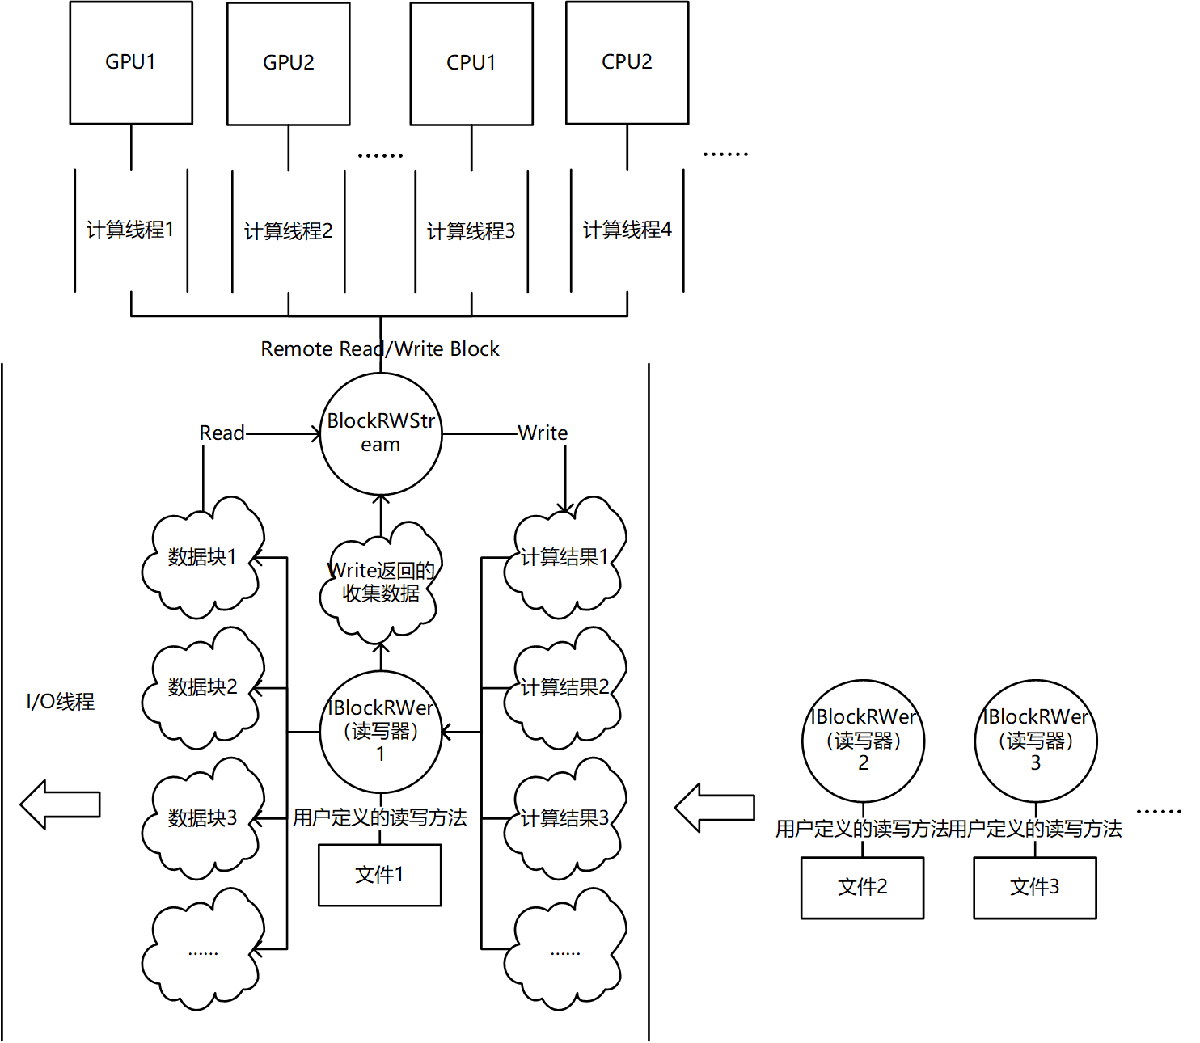

作为招牌，此方法展现了整个BlockRWStream类的设计思想：

- 用户告诉BlockRWStream，要读入的文件列表，和获取读写器的函数句柄，然后BlockRWStream会据此构造读写器，并收集IBlockRWer.Metadata保存起来。

- 启动并行计算线程。BlockRWStream负责在主线程和并行线程之间交流。SpmdRun会自动为每个线程分配硬件，为前几个线程分配GPU设备，后面的线程则只能分到CPU设备。

- 在SpmdRun的调度下，并行线程根据自己分配到的设备内存（GPU内存或CPU内存），通过BlockRWStream依次向I/O线程请求相应大小的数据块（考虑到运行时额外内存消耗，数据块通常比内存小）。I/O线程收到BlockRWStream.RemoteReadBlock请求，根据读写器提供的IBlockRWer.PieceSize属性，计算出数据块包含多少个数据片，然后将请求通过IBlockRWer.Read方法转交给读写器，由读写器实际执行用户定义的读入操作，读入数据块，然后再由BlockRWStream跨越线程边界将数据块返回给计算线程。

- 计算线程收到数据块后，SpmdRun会假定数据块是一个元胞数组，每个元胞内存放着一个要交给BlockProcess的参数。BlockProcess是用户定义的并行计算函数句柄。因此，用户定义的读写器Read方法，必须返回元胞数组才能适用于SpmdRun。

- 计算线程计算过程中，I/O线程可以继续执行其它计算线程的请求。计算完毕后，通过BlockRWStream.RemoteWriteBlock，将计算结果发给I/O线程，I/O线程同样转交给读写器。读写器按照用户定义的代码，将计算结果分流，一部分写出到文件，另一部分返还给BlockRWStream，返还的这部分会存放在BlockRWStream.BlockTable.ReturnData中。

- BlockRWStream会根据读写器提供的IBlockRWer.NumPieces属性判断文件是否已经读完。一旦读完，将为下一个文件新建读写器，以便继续读入数据块。此时上一个文件可能还有正在计算中的数据块，所以读写器会被暂时保留，直到该文件的最后一个数据块计算完毕，保存好计算结果后，读写器才被销毁。

- 所有文件读写完成后，所有读写器被销毁，并行线程结束。调用BlockRWStream.CollectReturn方法，会将之前收集在BlockRWStream.BlockTable.ReturnData中的数据按文件分类返回。同时也会返回从每个读写器收集到的IBlockRWer.Metadata。

- SpmdRun返回后，BlockRWStream对象即处于报废状态，只能收集返回值，无法重新运行，只能销毁重建。

## 语法

## 输入参数

BlockProcess，必需，用户提供的处理单个数据块的函数句柄。每次读入数据块后，SpmdRun会在并行计算线程上调用该函数。其输入参数可分为3类：

- 适用于GPU的数据块参数。如果希望使用GPU计算，将可以转换为gpuArray的参数放在BlockProcess参数列表最靠前的位置。SpmdRun会在将参数交给BlockProcess之前将这些参数转换为gpuArray。指定NumGpuArguments参数，这样SpmdRun才知道要将前几个参数转换为gpuArray。

- 不适用于GPU的数据块参数。有些参数不能转换为gpuArray，将它们放在BlockProcess参数列表中间的位置。

- 常量参数。这些参数与读入的数据块和文件无关，在整个工作流程中保持恒定。这部分参数放在BlockProcess参数列表的最后。然后将这些常量值作为重复参数交给SpmdRun的ConstantArgument参数，SpmdRun会保存这些常量值，每次调用BlockProcess时将它们传递。

BlockProcess会在多个独立的计算线程上并行运行，因此请勿在函数中使用共享静态资源，如persistent变量等。共享静态资源请通过IBlockRWer的Read方法（对于文件内相同、文件间不同的资源），或SpmdRun的ConstantArgument参数（文件间也相同）传入。

ConstantArgument，重复参数，提供给BlockProcess的常量参数。这些参数与当前读入的是哪个文件、第几个数据块均无关，在整个计算过程中保持为常量。SpmdRun会将这些参数保存起来，接在数据块参数之后交给BlockProcess，且值恒定不变。

Name=Value，可以指定以下名称值参数：

- NArgOut=0，BlockProcess的返回值个数。这些返回值将以元胞行向量形式交给读写器的Write方法。如果读写器未重写Write方法，将原封不动被收集到CollectData中。

- RuntimeCost=2，运行时实际将要占用的内存是数据块的多少倍。这是一个需要评估调校的性能参数。SpmdRun会根据当前内存自动设置要读取的数据块大小，但无法估计计算线程将额外占用多少内存，需要用户告知。此值过大将导致内存不足，过小则会导致内存得不到充分利用，数据块划分过多，尤其影响GPU的性能。因为GPU的并行计算特点，其计算时间与数据块大小无关，只与计算步骤个数有关。因此数据块划分越多，GPU计算越慢。应当在GPU内存充足的前提下尽可能读入更大的数据块。

- NumGpuArguments=0，前几个数据块参数要送入GPU运行。SpmdRun会自动检测当前GPU设备，尽可能将数据块送到GPU运行。但有些数据无法送入GPU，需要用户判断。请将可以送入GPU的数据块参数放在最前面，然后指定GPU参数个数。默认0，表示不使用GPU，只用CPU运算。

## 返回值

此函数最后会调用CollectReturn成员方法，直接返回该方法返回的CollectData和Metadata。

CollectData，一个元胞列向量，每个元胞对应一个文件的计算结果。元胞内又是元胞列向量，每个元胞对应一个数据块的计算结果，即计算线程每次调用Local/Remote WriteBlock时提供的Data参数，亦即读写器Write方法的返回值。每个数据块的计算结果将是一个元胞行向量，对应BlockProcess的每个返回值。例如，如果返回m×1元胞列向量，说明输入的文件有m个；其中第a个元胞内是n×1元胞列向量，说明第a个文件被分成了n块读入；其中第b个元胞内是1×p元胞行向量，说明BlockProcess有p个返回值。

Metadata，每个文件的元数据，为每个读写器的Metadata属性值，排列在元胞列向量中。

## 性能提示

SpmdRun会检测当前并行池类型。如果是parallel.ThreadPool（线程并行池），将改用 Local Read/Write Block 方法读写数据块，比Remote方法性能更高。如果当前没有并行池，将自动创建线程并行池

**See also** [ParallelComputing.BlockRWStream.CollectReturn](matlab:doc ParallelComputing.BlockRWStream.CollectReturn)

function [CollectData,Metadata]=SpmdRun(obj,BlockProcess,ConstantArgument,options)
arguments
	obj
	BlockProcess
end
arguments(Repeating)
	ConstantArgument
end
arguments
	options.NArgOut=0
	options.RuntimeCost=2
	options.NumGpuArguments=0
end
NumWorkers=ParallelComputing.ParPool(ProfileNameIfNew='Threads').NumWorkers;
[~,CpuMemory]=memory;
CpuMemory=CpuMemory.PhysicalMemory.Available/NumWorkers;
spmd
	CPU=spmdIndex>gpuDeviceCount||~options.NumGpuArguments;
	if CPU
		Memory=CpuMemory;
	else
		Memory=gpuDevice(spmdIndex).AvailableMemory;
	end
	Memory=Memory/options.RuntimeCost;
	%即使线程并行池也无法使用Local方法，会产生线程争用，而MATLAB缺少互斥锁，.NET互斥锁亦未知原因无法使用
	ArgOuts=obj.RemoteReadAsync(Memory).poll(Inf);
	[Data,Index]=ArgOuts{:};
	while ~ismissing(Data)
		IPollable=obj.RemoteReadAsync(Memory);
		varargout=cell(1,options.NArgOut);
		if CPU
			[varargout{:}]=BlockProcess(Data{:},ConstantArgument{:});
		else
			GpuIndex=1:options.NumGpuArguments;
			try
				Data(GpuIndex)=cellfun(@gpuArray,Data(GpuIndex),UniformOutput=false);
				[varargout{:}]=BlockProcess(Data{:},ConstantArgument{:});
				varargout=cellfun(@gather,varargout,UniformOutput=false);
			catch ME
				warning('GPU进程%u处理第%u块数据时出错：\n%s\n%s\n退回CPU处理',spmdIndex,Index,ME.identifier,ME.message);
				Data(GpuIndex)=cellfun(@gather,Data(GpuIndex),UniformOutput=false);
				[varargout{:}]=BlockProcess(Data{:},ConstantArgument{:});
				gpuDevice(spmdIndex);%此操作会让所有gpuArray无效，因此必须在gather回所有参数以后调用
			end
		end
		obj.RemoteWriteBlock(varargout,Index);
		ArgOuts=IPollable.poll(Inf);
		[Data,Index]=ArgOuts{:};
	end
end
[CollectData,Metadata]=obj.CollectReturn;
end